clear;
% load("C:\Users\htejada\GitHub\P1\IMG_9567.MOV.mat");
load("/Users/xavieryn/GitHub/P1/IMG_9567.MOV.mat");

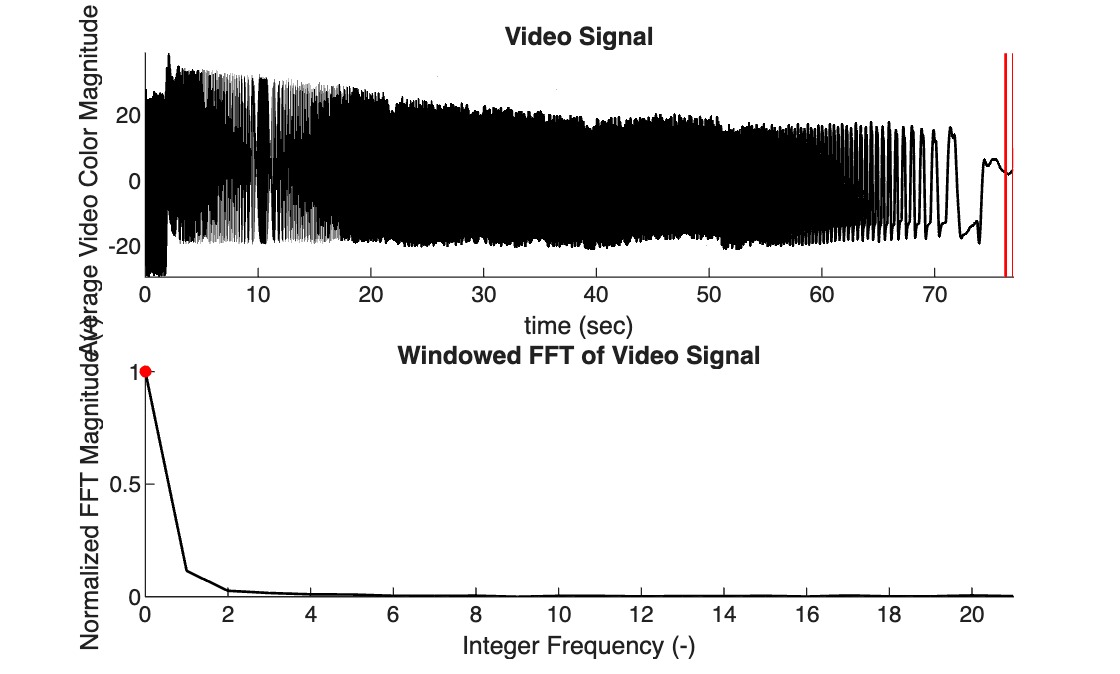

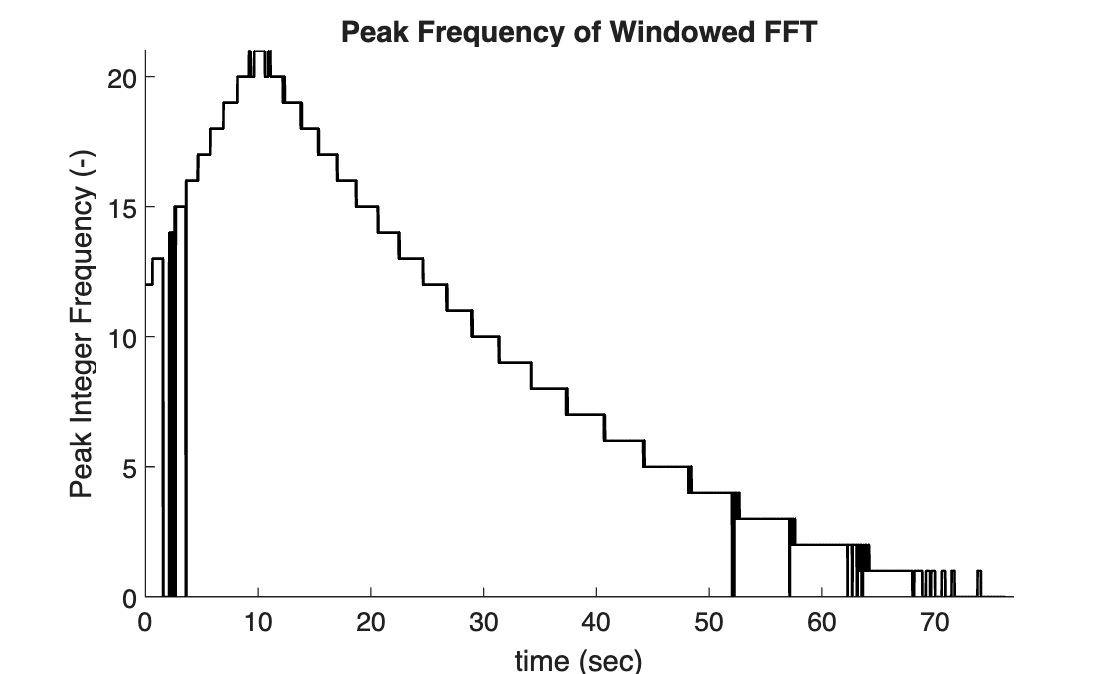

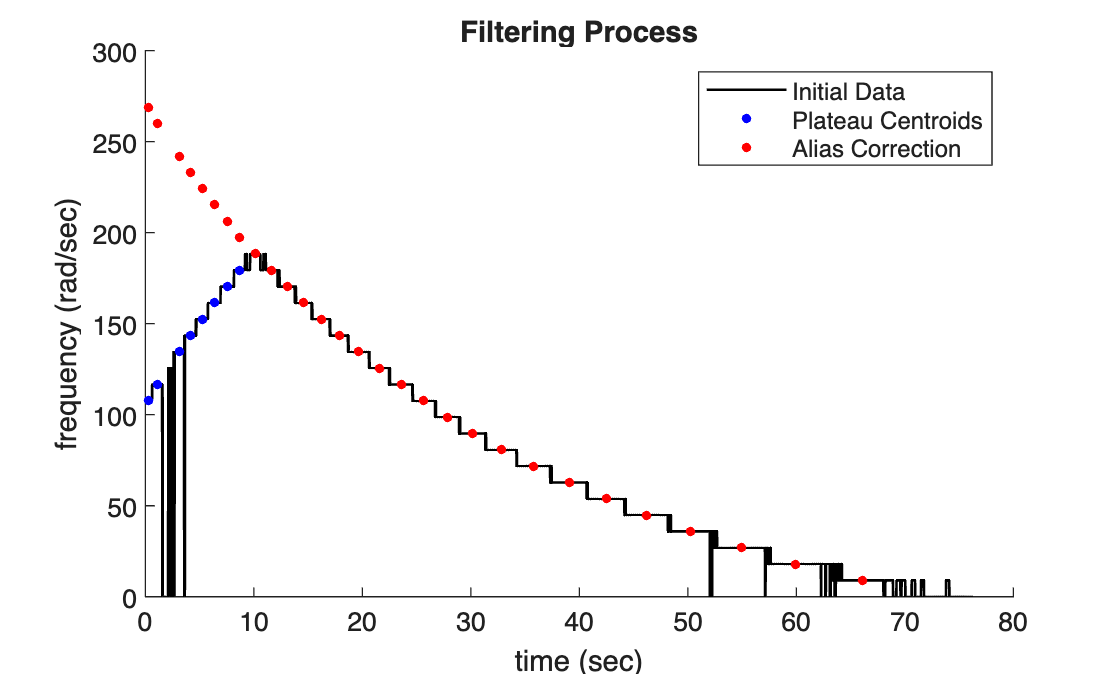

%T_window: width of FFT window (in seconds) .7 is usually good
T_window = .7;
%q: a parameter used to filter which portions of frequency curve to use
% (filter is by width of flat portions of curve)
% value should be in interval [0,1]
% values closer to 1 are most "exclusive".
% .6 is a pretty good value to choose
q = .6;
%showAnalysis: boolean that turns visualization on/off
showAnalysis = 1;
%uses FFT and some filtering tricks to extract angular velocity of fidget
%spinner as a function of time
%OUTPUTS:
%tlist: list of times for measured values of angular frequency
%omega_list: measured value of angular frequency
[tlist,freq_list] = fidget_spinner_FFT(y,Fs,T_window,q,showAnalysis);

% wTrue = wApparent/nWings
% true angular velocity = apparent / 3 wings
wTrue = freq_list / 3

wTrue =    89.6701   86.6811   80.7031   77.7141   74.7251   71.7361   68.7471   65.7581   62.7691   59.7801   56.7911   53.8021   50.8131   47.8241   44.8351   41.8461   38.8571   35.8680   32.8790   29.8900   26.9010   23.9120   20.9230   17.9340   14.9450   11.9560    8.9670    5.9780    2.9890


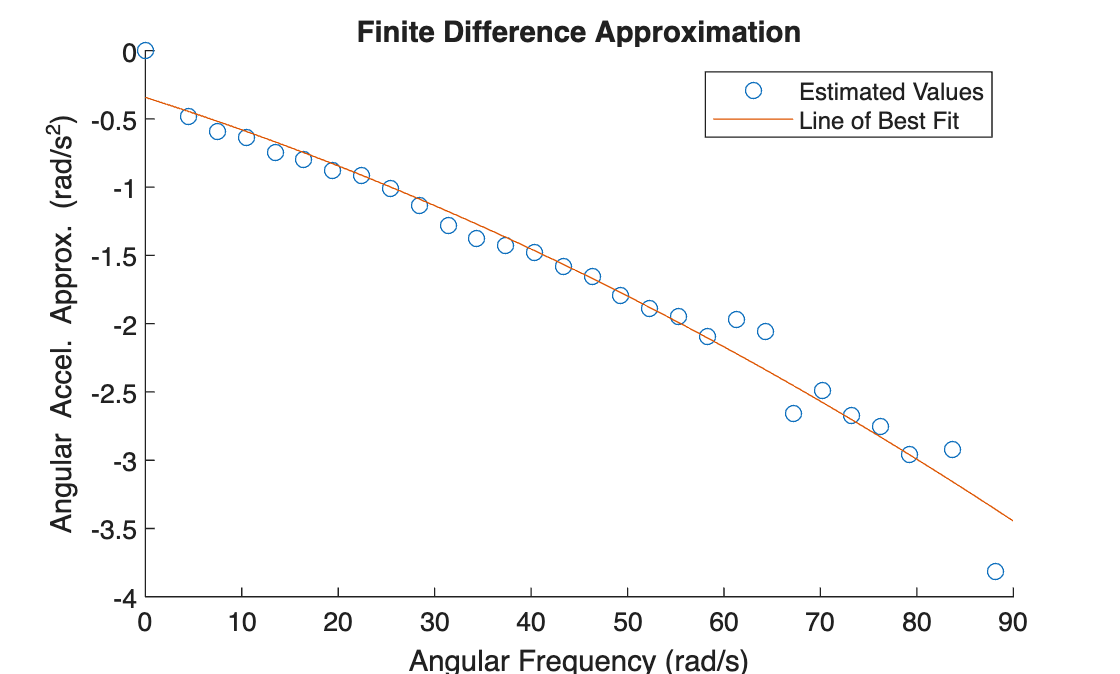

% Deliverable #6

ang_accel_approx = zeros(size(tlist, 2), 2);
ang_freq_points = zeros(size(tlist, 2), 2);

for i = 1:1:size(tlist, 2) - 1
    indexer = i + 0.5;
    approximation = (wTrue(i+1) - wTrue(i))/(tlist(i+1) - tlist(i));

    ang_accel_approx(i, :) = [indexer, approximation];

    tmp = (wTrue(i+1) + wTrue(i))/2;

    ang_freq_points(i, :) = [indexer, tmp];
end

figure
hold on
scatter(ang_freq_points(:, 2), ang_accel_approx(:, 2))
xlabel('Angular Frequency (rad/s)')
ylabel('Angular Accel. Approx. (rad/s^2)')

% Get Polyfit
coeff = polyfit(ang_freq_points(:, 2), ang_accel_approx(:, 2), 2);
line_best_fit = @(omega) coeff(1) * omega.^2 + coeff(2) * omega + coeff(3);
t_vals = linspace(0, 90, 100);
best_fit_vals = line_best_fit(t_vals);

plot(t_vals, best_fit_vals)

title('Finite Difference Approximation')
legend('Estimated Values', 'Line of Best Fit')

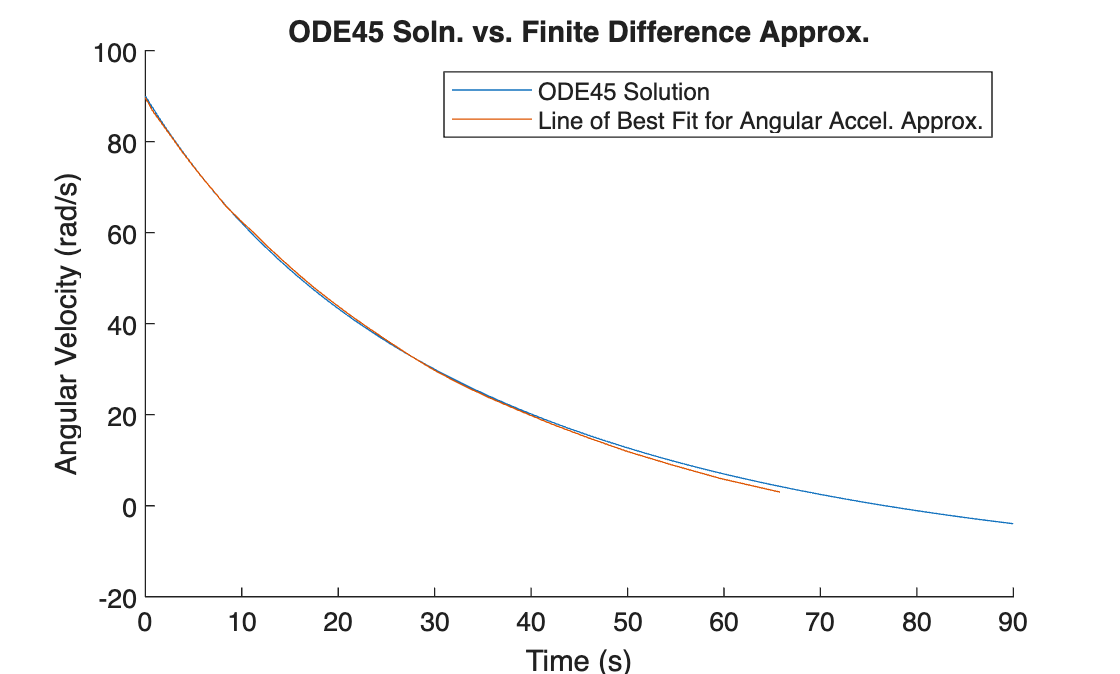

% Deliverable 9-10
line_best_fit = @(t, omega) coeff(1) * omega^2 + coeff(2) * omega + coeff(3);
[x, y] = ode45(line_best_fit, t_vals, 90);
figure
hold on
plot(x, y)
plot(tlist, wTrue)

title('ODE45 Soln. vs. Finite Difference Approx.')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
legend('ODE45 Solution', 'Line of Best Fit for Angular Accel. Approx.')

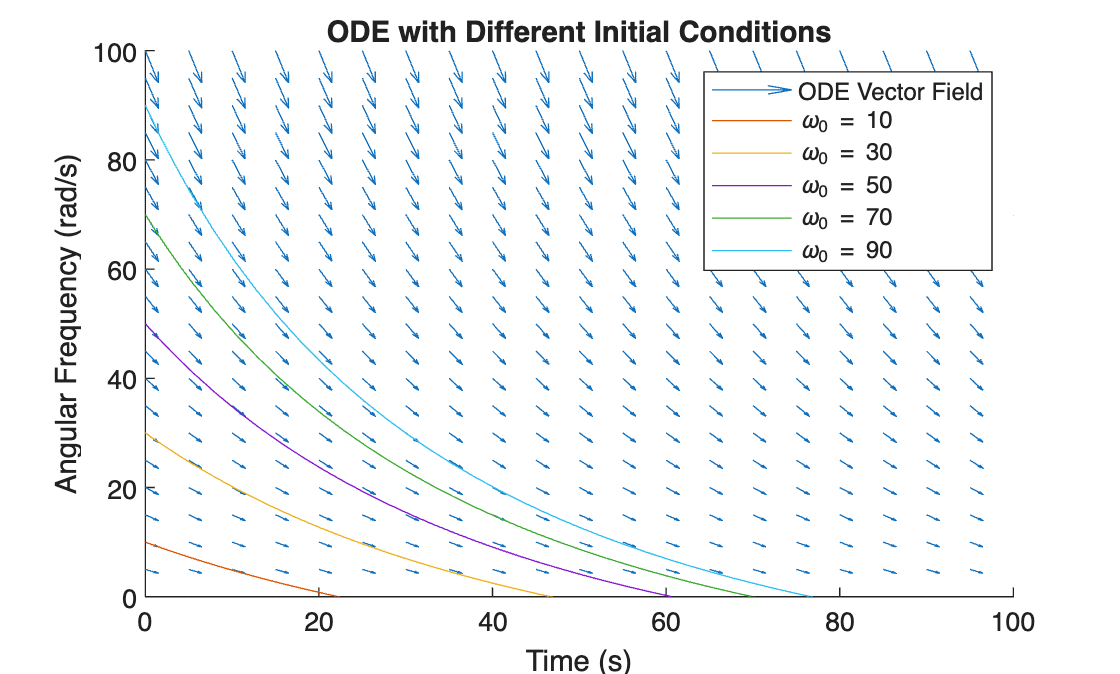

% Deliverable 11
line_best_fit = @(t, omega) coeff(1) * omega.^2 + coeff(2) * omega + coeff(3);

figure
hold on
[T, X] = meshgrid(linspace(0, 100, 21), linspace(0, 100, 21));
U = ones(size(T));
V = line_best_fit(T, X);
quiver(T, X, U, V, DisplayName='ODE Vector Field')
xlabel("Time (s)")
ylabel("Angular Frequency (rad/s)")
title("ODE with Different Initial Conditions")

for C = [10, 30, 50, 70, 90]
    [t, rad] = ode45(line_best_fit, [0, 100], C);
    plot(t, rad, DisplayName=['\omega_0 = ' num2str(C)])
end

axis([0, 100, 0 100]);
legend


% Deliverable 11

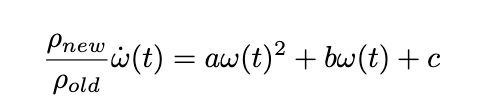

multiply Pold/Pnew on both sides and then plug that in for ODE

% Now adding pnew and pold 
poldDpnew = [0.5 1 2]

poldDpnew =     0.5000    1.0000    2.0000


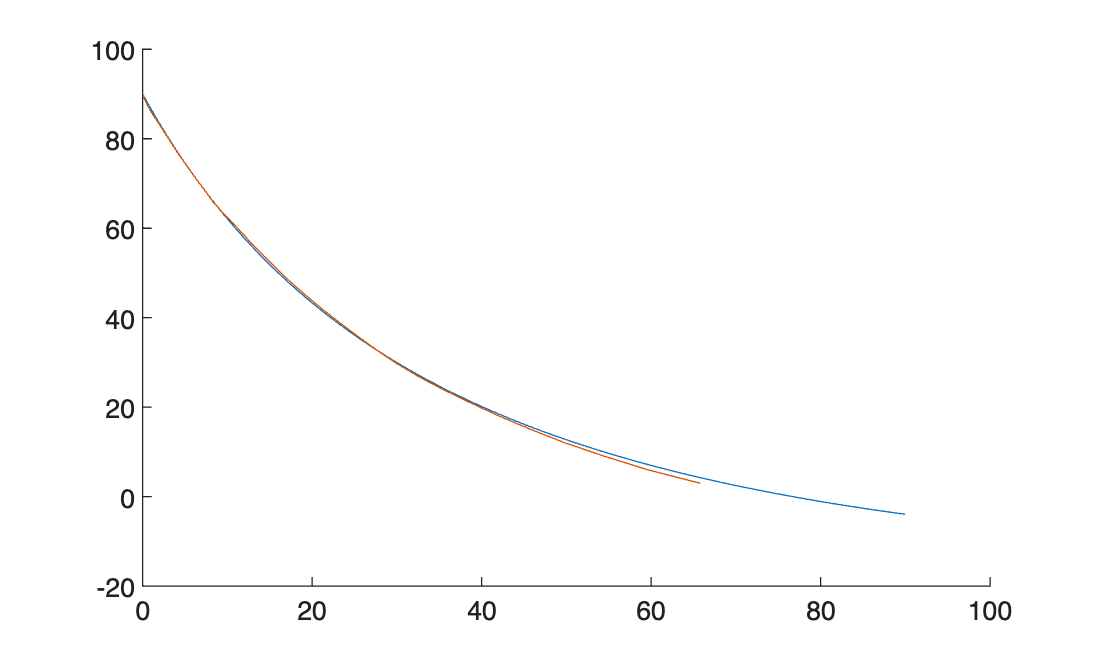


line_best_fit = @(t, omega) coeff(1) * omega^2 + coeff(2) * omega + coeff(3);
[x, y] = ode45(line_best_fit, t_vals, 90);
figure
hold on
plot(x, y)
plot(tlist, wTrue)

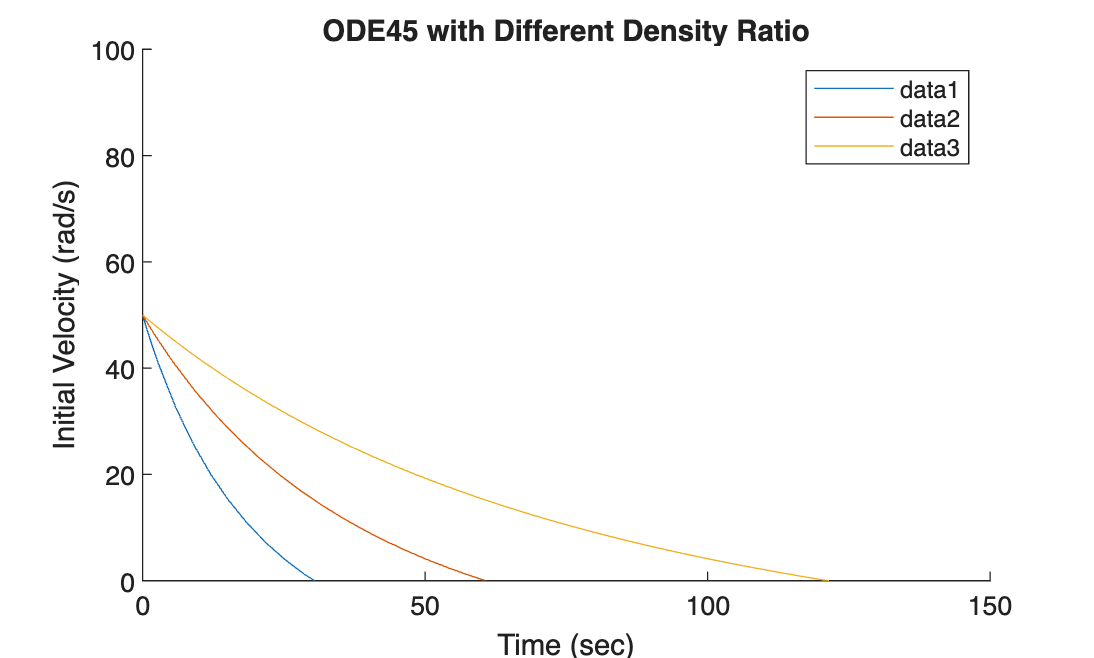


figure
hold on
title("ODE45 with Different Density Ratio");
xlabel("Time (sec)");
ylabel("Initial Velocity (rad/s)");
% [T, X] = meshgrid(linspace(0, 100, 51), linspace(0, 100, 51));
% U = ones(size(T));
% V = line_best_fit(T, X);
% quiver(T, X, U, V)
% xlabel("Time (s)")
% ylabel("Angular Frequency (rad/s)")
% title("Visualizing a Differential Equation as a Vector Field")
% hold on

for poldDpnew = [2 1 .5]
    line_best_fit = @(t, omega) poldDpnew*coeff(1) * omega.^2 + poldDpnew*coeff(2) * omega + poldDpnew*coeff(3);
    [t, rad] = ode45(line_best_fit, [0, 150], 50);
    plot(t, rad)
end

axis([0, 150, 0 100]);
legend

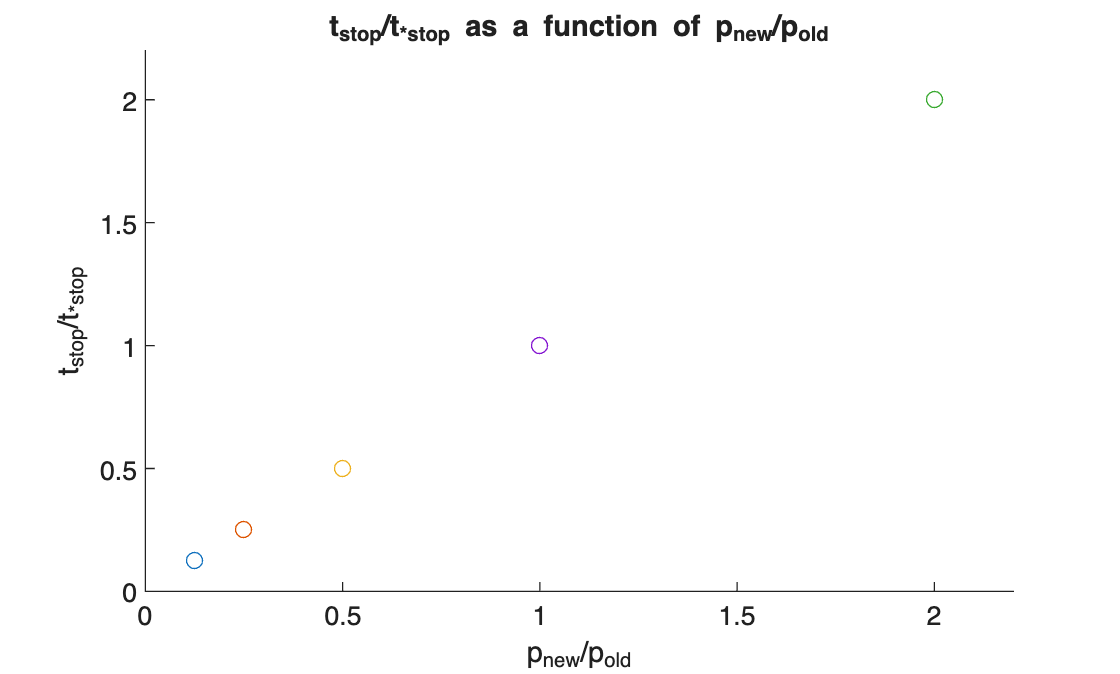

figure
hold on
title("t_{stop}/t_{*stop} as a function of p_{new}/p_{old}");
xlabel("p_{new}/p_{old}");
ylabel("t_{stop}/t_{*stop}");
tspan = linspace(0, 150, 1000);  % 1000 points from 0 to 150

for poldDpnew = [8 4 2 1 0.5 ]
    tstop = @(t, omega) poldDpnew*coeff(1) * omega.^2 + poldDpnew*coeff(2) * omega + poldDpnew*coeff(3);
    tstarstop = @(t, omega) coeff(1) * omega.^2 + coeff(2) * omega + coeff(3);

    [tstopval, rad] = ode45(tstop, tspan, 50);
    [tstarstopval, radstar] = ode45(tstarstop, tspan, 50);

    [~, idx] = min(abs(rad));
    [~, idxstar] = min(abs(radstar));

    t_closest_to_zero = tstopval(idx);
    t_closest_to_zerostar = tstarstopval(idxstar);  % fixed

    tstopDtstarstop = t_closest_to_zero / t_closest_to_zerostar;

    plot(1/poldDpnew, tstopDtstarstop, 'o')  % add marker so single point is visible
    % 1/poldDpnew makes it to pnew/pold which is what t stop asks for 
end

% Get current axis limits
xlimits = xlim;
ylimits = ylim;

% Add a little buffer (10%) to the top/right
axis([0, xlimits(2)*1.1, 0, ylimits(2)*1.1])